# Meta 2: Processamento Espectral

## 10. Carregamento da estrutura de dados

load('AED1.mat');

% Número de arquivos (linhas da tabela)
nArquivos = height(tab);

% Verifica se o campo CoeficientesFourier existe e se é um cell array
if ~isfield(tab, 'CoeficientesFourier') || ~iscell(tab.CoeficientesFourier)
    % Se não existir ou não for cell, cria um cell array do tamanho correto
    tab.CoeficientesFourier = cell(nArquivos,1);
end

## 11. Cálculo dos Coeficientes da Série Complexa de Fourier

for i = 1:nArquivos
    sinal = tab.Sinal_Processado{i};  % Recupera o sinal processado
    tab.CoeficientesFourier{i} = fft(sinal);  % Calcula e armazena os coeficientes
end

% Salva a tabela atualizada
save('AED1.mat', 'tab');
disp(tab);

                            Diretorio_Audio                             Nome_Arquivo      Digito    Participante    Repeticao    Sinal_Processado    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    FatorCrest    TaxaCruzamento    CoeficientesFourier
    _______________________________________________________________    _______________    ______    ____________    _________    ________________    _______________    ____________    _____________________    ___________________

## 12. Cálculo e Visualização do Espectro de Amplitude Mediano e Quartis

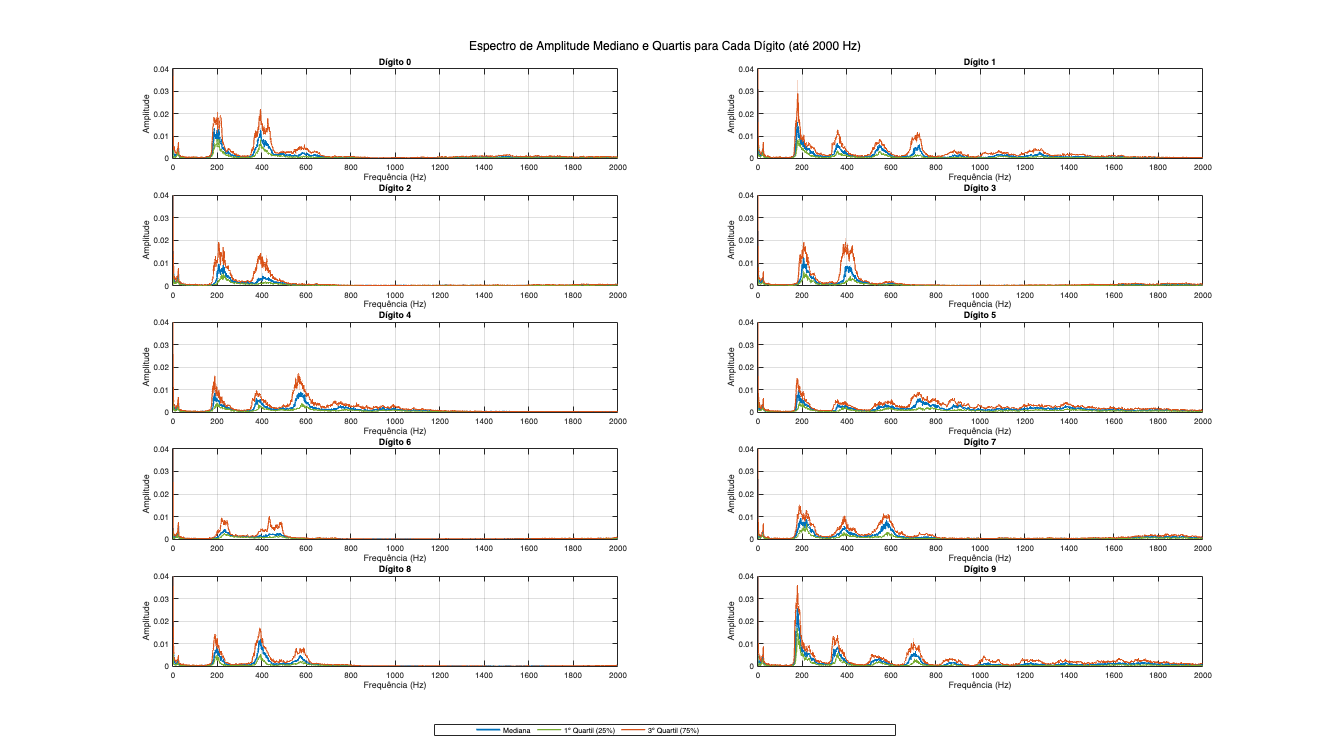

% Identifica os dígitos únicos
digitosUnicos = unique(tab.Digito);
numDigitos = numel(digitosUnicos);

figure('Name', 'Espectro de Amplitude Mediano e Quartis por Dígito', ...
       'Units','normalized','OuterPosition',[0 0 1 1]);

% Handles para legenda do primeiro subplot
hMed = []; hQ1 = []; hQ3 = [];

for k = 1:numDigitos
    digitoAtual = digitosUnicos(k);
    idx = find(tab.Digito == digitoAtual);
    numSinais = numel(idx);
    
    % Utiliza o primeiro sinal para obter a taxa de amostragem e tamanho do sinal
    sinalExemplo = tab.Sinal_Processado{idx(1)};
    fs = tab.Taxa_Amostragem(idx(1));
    N = length(sinalExemplo);
    
    % Índices para frequências positivas
    idxPositivos = 1:floor(N/2)+1;
    f = (idxPositivos - 1) * fs / N;
    
    % Seleciona apenas as frequências até 2000 Hz
    idxCorte = find(f <= 2000);
    f_corte = f(idxCorte);
    
    % Prealoca a matriz para armazenar os espectros de amplitude
    espectros = zeros(length(idxCorte), numSinais);
    for j = 1:numSinais
        sinal = tab.Sinal_Processado{idx(j)};
        fftSinal = fft(sinal) / N;           % FFT normalizada pelo número de amostras
        espectro = abs(fftSinal(idxPositivos));  % Espectro para frequências positivas
        espectros(:, j) = espectro(idxCorte);
    end
    
    % Calcula a mediana, 1º quartil (25%) e 3º quartil (75%) para cada frequência
    mediana = median(espectros, 2);
    q1 = quantile(espectros, 0.25, 2);
    q3 = quantile(espectros, 0.75, 2);
    
    subplot(ceil(numDigitos / 2), 2, k);
    % Plot com cores diferenciadas
    h1 = plot(f_corte, mediana, 'Color', [0 0.4470 0.7410], 'LineWidth', 2); hold on;
    h2 = plot(f_corte, q1, 'Color', [0.4660 0.6740 0.1880], 'LineWidth', 1.5);
    h3 = plot(f_corte, q3, 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 1.5);
    hold off;
    
    xlabel('Frequência (Hz)');
    ylabel('Amplitude');
    title(sprintf('Dígito %d', digitoAtual));
    grid on;
    ylim([0, 0.04]);
    
    % Guarda os handles do primeiro subplot para legenda
    if k == 1
        hMed = h1;
        hQ1 = h2;
        hQ3 = h3;
    end
end

% Cria uma legenda comum para todos os subplots, posicionada na parte inferior
legend([hMed, hQ1, hQ3], {'Mediana','1º Quartil (25%)','3º Quartil (75%)'}, ...
       'Orientation', 'horizontal', 'Position', [0.35 0.01 0.3 0.03]);

sgtitle('Espectro de Amplitude Mediano e Quartis para Cada Dígito (até 2000 Hz)');

## 13. Cálculo das Características Espectrais

% Pre-aloca os vetores de características (garante que sejam colunas de tamanho nArquivos)
AmpEspectralMaxima   = zeros(nArquivos, 1);
FreqAmpMaxima       = zeros(nArquivos, 1);
CentroideEspectral  = zeros(nArquivos, 1);
FreqBordaEspectral  = zeros(nArquivos, 1);
LarguraBandaEspectral = zeros(nArquivos, 1);

for i = 1:nArquivos
    sinal = tab.Sinal_Processado{i};
    if isempty(sinal)
        continue;
    end
    
    N = length(sinal);
    fs = tab.Taxa_Amostragem(i);
    Y = fft(sinal);
    magEspectro = abs(Y) / N;
    
    % Considera somente as frequências positivas
    numFreqPos = floor(N/2) + 1;
    magEspectro = magEspectro(1:numFreqPos);
    f = linspace(0, fs/2, numFreqPos)';
    
    % 1. Amplitude Espectral Máxima e a frequência correspondente
    [ampMax, idxMax] = max(magEspectro);
    AmpEspectralMaxima(i) = ampMax;
    FreqAmpMaxima(i) = f(idxMax);
    
    % 2. Centroide Espectral (média ponderada das frequências)
    if sum(magEspectro) > 0
        CentroideEspectral(i) = sum(f .* magEspectro) / sum(magEspectro);
    else
        CentroideEspectral(i) = 0;
    end
    
    % 3. Frequência de Borda Espectral (frequência abaixo da qual 90% da energia está contida)
    energiaAcumulada = cumsum(magEspectro);
    energiaTotal = energiaAcumulada(end);
    idxBorda = find(energiaAcumulada >= 0.9 * energiaTotal, 1);
    FreqBordaEspectral(i) = f(idxBorda);
    
    % 4. Largura de Banda Espectral (desvio padrão das frequências ponderado pelo espectro)
    if sum(magEspectro) > 0
        LarguraBandaEspectral(i) = sqrt(sum(((f - CentroideEspectral(i)).^2) .* magEspectro) / sum(magEspectro));
    else
        LarguraBandaEspectral(i) = 0;
    end
end

% Atualiza a estrutura de dados com as novas características espectrais
tab.AmpEspectralMaxima = AmpEspectralMaxima;
tab.FreqAmpMaxima = FreqAmpMaxima;
tab.CentroideEspectral = CentroideEspectral;
tab.FreqBordaEspectral = FreqBordaEspectral;
tab.LarguraBandaEspectral = LarguraBandaEspectral;

% Exibe a tabela atualizada e salva em arquivo
disp(tab);

                            Diretorio_Audio                             Nome_Arquivo      Digito    Participante    Repeticao    Sinal_Processado    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    FatorCrest    TaxaCruzamento    CoeficientesFourier    AmpEspectralMaxima    FreqAmpMaxima    CentroideEspectral    FreqBordaEspectral    LarguraBandaEspectral
    _______________________________________________________________    _______________    ______    ____________    ____

## 14. Visualização das Características Espectrais

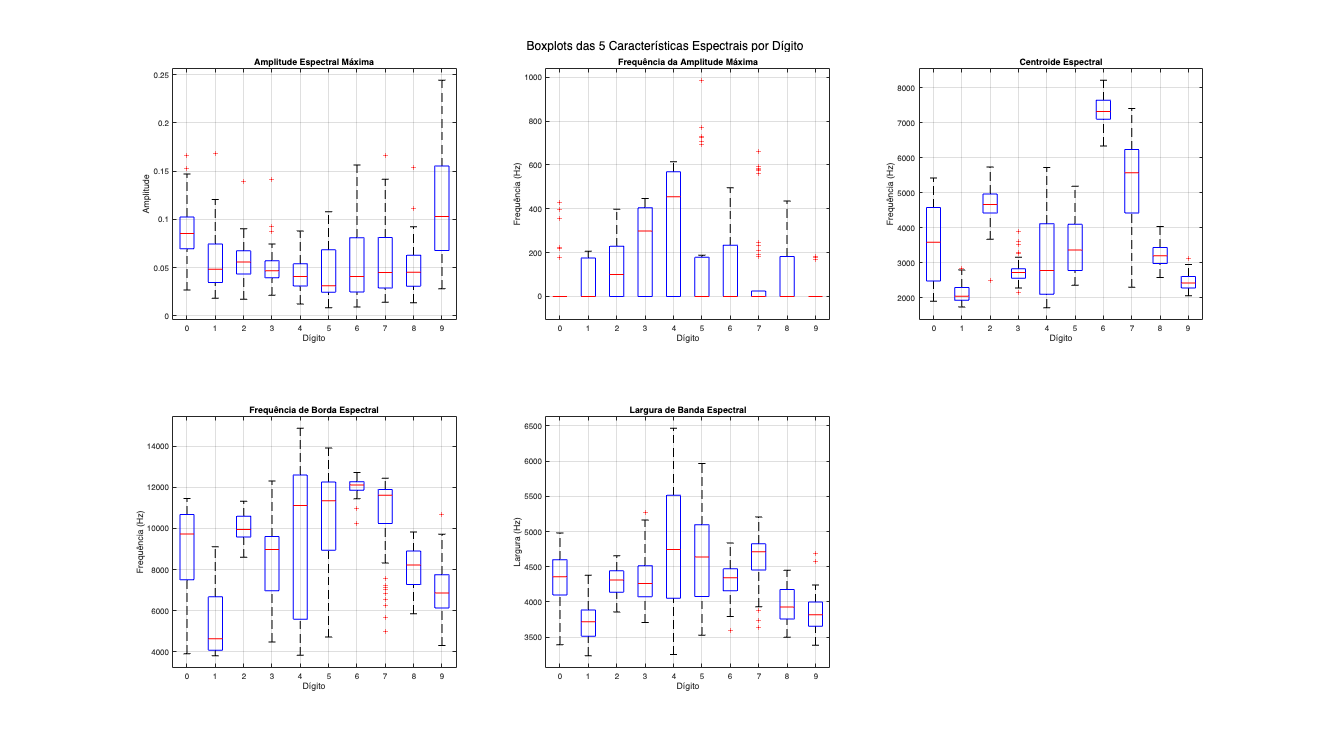

% Boxplots das 5 características espectrais por dígito
figure('Name','Boxplots das 5 Características Espectrais por Dígito','Units','normalized','OuterPosition',[0 0 1 1]);

% Boxplot para AmpEspectralMaxima (Amplitude Espectral Máxima)
subplot(2,3,1);
boxplot(tab.AmpEspectralMaxima, tab.Digito);
xlabel('Dígito');
ylabel('Amplitude');
title('Amplitude Espectral Máxima');
grid on;

% Boxplot para FreqAmpMaxima (Frequência da Amplitude Máxima)
subplot(2,3,2);
boxplot(tab.FreqAmpMaxima, tab.Digito);
xlabel('Dígito');
ylabel('Frequência (Hz)');
title('Frequência da Amplitude Máxima');
grid on;

% Boxplot para CentroideEspectral (Centroide Espectral)
subplot(2,3,3);
boxplot(tab.CentroideEspectral, tab.Digito);
xlabel('Dígito');
ylabel('Frequência (Hz)');
title('Centroide Espectral');
grid on;

% Boxplot para FreqBordaEspectral (Frequência de Borda Espectral)
subplot(2,3,4);
boxplot(tab.FreqBordaEspectral, tab.Digito);
xlabel('Dígito');
ylabel('Frequência (Hz)');
title('Frequência de Borda Espectral');
grid on;

% Boxplot para LarguraBandaEspectral (Largura de Banda Espectral)
subplot(2,3,5);
boxplot(tab.LarguraBandaEspectral, tab.Digito);
xlabel('Dígito');
ylabel('Largura (Hz)');
title('Largura de Banda Espectral');
grid on;

sgtitle('Boxplots das 5 Características Espectrais por Dígito');

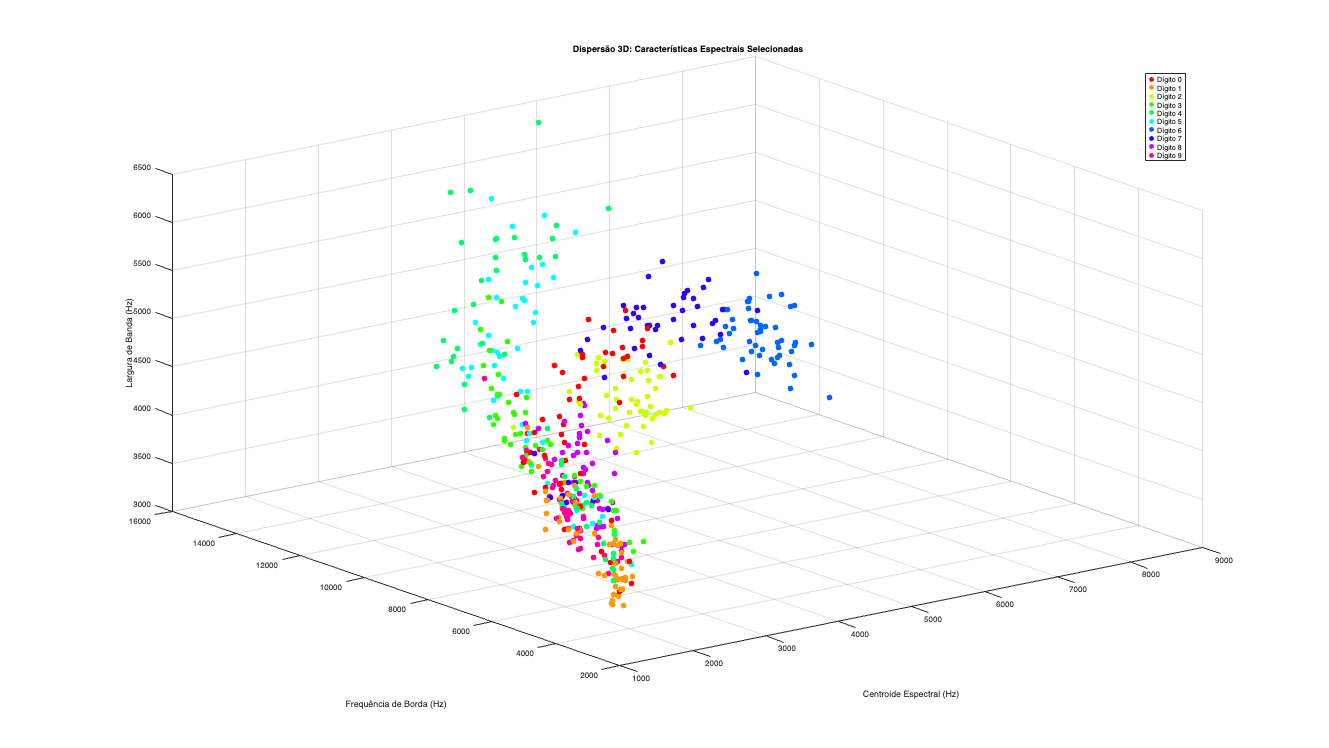


% Dispersão 3D: Características Espectrais Selecionadas
figure('Name','Dispersão 3D: Características Espectrais Selecionadas','Units','normalized','OuterPosition',[0 0 1 1]);
digitosUnicos = unique(tab.Digito);
numDigitos = numel(digitosUnicos);
cores = hsv(numDigitos);

hold on;
handlesDisp = gobjects(numDigitos,1);
for k = 1:numDigitos
    idx = (tab.Digito == digitosUnicos(k));
    handlesDisp(k) = scatter3(tab.CentroideEspectral(idx), tab.FreqBordaEspectral(idx), tab.LarguraBandaEspectral(idx), 50, cores(k,:), 'filled');
end
hold off;

xlabel('Centroide Espectral (Hz)');
ylabel('Frequência de Borda (Hz)');
zlabel('Largura de Banda (Hz)');
title('Dispersão 3D: Características Espectrais Selecionadas');
grid on;
view(3); % Visualização em 3D

% Cria legenda para os dígitos
entradasLegenda = arrayfun(@(d) sprintf('Dígito %d', d), digitosUnicos, 'UniformOutput', false);
legend(handlesDisp, entradasLegenda, 'Location', 'best');

## 15. Salva a tabela atualizada

save('AED1.mat', 'tab');
disp(tab);

                            Diretorio_Audio                             Nome_Arquivo      Digito    Participante    Repeticao    Sinal_Processado    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    FatorCrest    TaxaCruzamento    CoeficientesFourier    AmpEspectralMaxima    FreqAmpMaxima    CentroideEspectral    FreqBordaEspectral    LarguraBandaEspectral
    _______________________________________________________________    _______________    ______    ____________    ____